cd(fileparts(matlab.desktop.editor.getActiveFilename))
close all; clearvars; clc

load("../../results/trmse_raw.mat")

seq_starts = find(y_within.w_trial==1)+1

seq_starts =      2
    11
    20
    29
    38
    47


seq_stops = find(y_within.w_trial==9)+1

seq_stops =     10
    19
    28
    37
    46
    55


num_subjs = height(y_between);
num_slopes =numel(seq_starts);
lin_fit_arr = zeros(num_subjs, num_slopes);
for i=1:num_subjs
    for j=1:num_slopes
        seq = y_between{i, seq_starts(j):seq_stops(j)};
        [lin_fit, lin_gof] = fit((1:9)',seq',"poly1");
        lin_fit_arr(i,j) = lin_fit.p1;
        % [lin_fit, lin_gof] = fit((1:9)',seq',"exp1", 'StartPoint', [0.6, -0.2]);
        % lin_fit_arr(i,j) = lin_fit.b;
    end
end

m_between = array2table(lin_fit_arr)

m_between = 14×6 table
    lin_fit_arr1    lin_fit_arr2    lin_fit_arr3    lin_fit_arr4    lin_fit_arr5    lin_fit_arr6
    ____________    ____________    ____________    ____________    ____________    ____________

      -0.011866     -0.00031137      -0.0010609      -0.0023138      -0.0040747      -0.0099145 
      0.0092427       0.0098808       0.0054749       -0.012332      -0.0077056       -0.016487 
       0.010131       0.0043692       -0.010856        0.050475      -0.0038504       -0.039751 
      -0.028532      -0.0090203       0.0080586      -0.0063009       -0.016703        -0.01329 
        -0.0372       -0.063831       0.0036897        0.027841       -0.021885       -0.029344 
      -0.057194       -0.035109       0.0013017        0.022277       -0.022815       -0.0107

m_between = [y_between(:,1), m_between]

m_between = 14×7 table
    b_condition    lin_fit_arr1    lin_fit_arr2    lin_fit_arr3    lin_fit_arr4    lin_fit_arr5    lin_fit_arr6
    ___________    ____________    ____________    ____________    ____________    ____________    ____________

      "par"          -0.011866     -0.00031137      -0.0010609      -0.0023138      -0.0040747      -0.0099145 
      "xpar"         0.0092427       0.0098808       0.0054749       -0.012332      -0.0077056       -0.016487 
      "par"           0.010131       0.0043692       -0.010856        0.050475      -0.0038504       -0.039751 
      "xpar"         -0.028532      -0.0090203       0.0080586      -0.0063009       -0.016703        -0.01329 
      "par"            -0.0372       -0.063831       0.0036897    

m_within = y_within(y_within.w_trial==1,["w_task", "w_gesture"])

m_within = 6×2 table
            w_task                w_gesture    
    ______________________    _________________

    "Machine Learning"        "Co-Activation"  
    "Machine Learning"        "Differentiation"
    "Human Learning"          "Co-Activation"  
    "Human Learning"          "Differentiation"
    "Co-Adaptive Learning"    "Co-Activation"  
    "Co-Adaptive Learning"    "Differentiation"


tlo = tiledlayout('flow');
fontsize(tlo, 20, "points")
% tlo.Units = 'inches';
% tlo.OuterPosition = [0 0 17 10.5];
ax_handle_list = [];
for cond = ["par", "xpar", "hlt"]
    y_cond = m_between(m_between.b_condition==cond,2:end);
    for task = ["Machine Learning", "Human Learning", "Co-Adaptive Learning"]
        y_coact = y_cond(:, and(m_within.w_task == task, m_within.w_gesture == "Co-Activation"));
        y_diffact = y_cond(:, and(m_within.w_task == task, m_within.w_gesture == "Differentiation"));
        ax_handle = nexttile;
        ax_handle_list = [ax_handle_list, ax_handle];
        hold on
        boxchart([y_coact{:,:};y_diffact{:,:}])
        scatter(ones(size(y_coact)), y_coact{:,:}, 175, 'o', 'MarkerFaceColor','k', 'MarkerEdgeColor','none', 'MarkerFaceAlpha',0.3)
        scatter(ones(size(y_diffact)), y_diffact{:,:}, 175, 'v', 'MarkerFaceColor',"#8c8c8c", 'MarkerEdgeColor', 'none','MarkerFaceAlpha',0.25)
        hold off
        title(task)
        switch task
            case "Machine Learning"
                title(task, 'Color', "#f0a150")
            case "Human Learning"
                title(task, 'Color', "#c76706")
            case "Co-Adaptive Learning"
                title(task, 'Color', "#f48020")
        end
        switch cond
            case "par"
                subtitle("Paretic", 'Color', "#b30600")
            case "xpar"
                subtitle("Nonparetic", 'Color', "#3760e3")
            case "hlt"
                subtitle("Healthy", 'Color', "#29af34")
        end
        % xticks(1:9)
        yticks(-0.05:0.025:0.05)
    end
end
legend_handle = legend(["Co-Activation (Power)", "", "", "Differential Activation (Tripod)"], "Location","eastoutside");

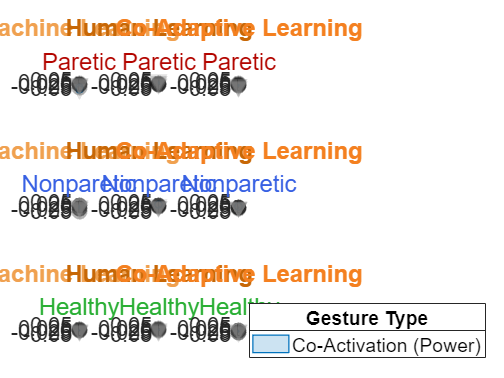

title(legend_handle, "Gesture Type")
linkaxes(ax_handle_list, 'xy')
ylim(1.1*[min(lin_fit_arr,[], 'all'), max(lin_fit_arr,[], 'all')])
% xlim([0 2])
% title(tlo, sprintf("%s Vs. Trial Count", upper(metric_type)))
set(ax_handle_list, 'FontSize', 18)

### Export to R

r_dataframe = [];
for i=1:height(m_between)
    if or(m_between{i,1} == "par", m_between{i,1} == "xpar")
        p_id = i+mod(i,2);
    else
        p_id = i;
    end
    p_tbl = array2table([m_between{i,2:end}', repmat(sprintf("p%02d",p_id), height(m_within),1), repmat(m_between{i,1}, height(m_within),1), m_within{:,:}], ...
        "VariableNames", ["rmse", "p_id", "p_cond", "task_type", "gesture_type"]);
    r_dataframe = [r_dataframe; p_tbl];
end

r_dataframe = convertvars(r_dataframe, ["rmse"], 'double');
r_dataframe = convertvars(r_dataframe, ["gesture_type", "task_type", "p_cond", "p_id"], 'categorical');
r_dataframe = r_dataframe(:,{'rmse' 'gesture_type' 'task_type' 'p_cond', 'p_id'})

r_dataframe = 84×5 table
       rmse         gesture_type           task_type          p_cond    p_id
    ___________    _______________    ____________________    ______    ____

      -0.011866    Co-Activation      Machine Learning         par      p02 
    -0.00031137    Differentiation    Machine Learning         par      p02 
     -0.0010609    Co-Activation      Human Learning           par      p02 
     -0.0023138    Differentiation    Human Learning           par      p02 
     -0.0040747    Co-Activation      Co-Adaptive Learning     par      p02 
     -0.0099145    Differentiation    Co-Adaptive Learning     par      p02 
      0.0092427    Co-Activation      Machine Learning         xpar     p02 
      0.0098808    Differentiation    Machine Learning         xpar     p02 
      0.0054749    Co-Activation  

writetable(r_dataframe, '../../temp-data/rdf_rmse_slope_9.csv','WriteMode','overwrite')

### 2-Way ANOVA

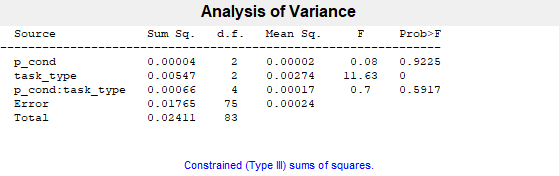

pvals =     0.9225
    0.0000
    0.5917


anova_tbl = 6×7 cell array
    {'Source'          }    {'Sum Sq.'   }    {'d.f.'}    {'Singular?'}    {'Mean Sq.'  }    {'F'       }    {'Prob>F'    }
    {'p_cond'          }    {[3.7993e-05]}    {[   2]}    {[        0]}    {[1.8996e-05]}    {[  0.0807]}    {[    0.9225]}
    {'task_type'       }    {[    0.0055]}    {[   2]}    {[        0]}    {[    0.0027]}    {[ 11.6257]}    {[4.0003e-05]}
    {'p_cond:task_type'}    {[6.6284e-04]}    {[   4]}    {[        0]}    {[1.6571e-04]}    {[  0.7040]}    {[    0.5917]}
    {'Error'           }    {[    0.0177]}    {[  75]}    {[        0]}    {[2.3539e-04]}    {0×0 double}    {0×0 double  }
    {'Total'           }    {[    0.0241]}    {[  83]}    {[        0]}    {0×0 double  }    {0×0 double}    {0×0 double  }


stats = struct with fields:
         source: 'anovan'
          resid: [84×1 double]
         coeffs: [16×1 double]
            Rtr: [9×9 double]
       rowbasis: [9×16 double]
            dfe: 75
            mse: 2.3539e-04
    nullproject: [16×9 double]
          terms: [3×2 double]
        nlevels: [2×1 double]
     continuous: [0 0]
         vmeans: [2×1 double]
       termcols: [4×1 double]
     coeffnames: {16×1 cell}
           vars: [16×2 double]
       varnames: {2×1 cell}
       grpnames: {2×1 cell}
        vnested: []
            ems: [4×4 double]
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


terms =      1     0
     0     1
     1     1


[pvals,anova_tbl,stats, terms] = anovan(r_dataframe{:,"rmse"}, ...
    {r_dataframe{:,"p_cond"}, r_dataframe{:,"task_type"}}, ...
    'varnames',["p_cond", "task_type"], ...
    'model',2)

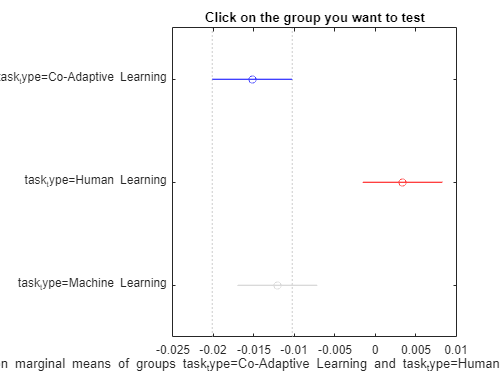

ans =     1.0000    2.0000   -0.0284   -0.0186   -0.0087    0.0001
    1.0000    3.0000   -0.0129   -0.0031    0.0068    0.7349
    2.0000    3.0000    0.0056    0.0155    0.0253    0.0010


figure
multcompare(stats, "Dimension",[2])